# **Image Processing**

If you have ever got hold of a simple image processsing tool -- Photoshop, filters in camera app, social media apps, etc, you might have at least once used the blur or the sharpen tool. The idea is simple - pick a blur tool of a preset radius, hold and drag across the image to blur out (or sharpen) certain regions in the image.

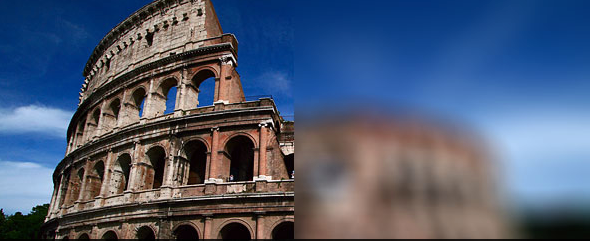 

## **Blur tool**

An MRI scan is provided in the csv format. Load `kidney.csv` and save it to the variable `image`. Save the number of rows to variable `M` and number of cols to the variable `N, `using the size function. Do NOT hand type the values (you will lose a point here). You code must be able to find the size of the image automatically. The `size()` function has two outputs rows and cols in a 2x1 array. Save the first element of the output to M and the second to N.

Read csv file
image = ?;
[M, N] = ?;

Create a duplicate of your image to another variable `blur`. Plot `image `and `blur `using the `subplot` function (2 rows, 1 col). Use `imshow()`  to plot images.

blur = ?;
figure()
subplot 
imshow(?);
subplot 
??

At this point both images should appear identical. We will now apply the blur tool on the image and detect the point with the highest intensity along the way. The blur kernel (I) here is a simple 3x3 unit matrix (use: `ones()`)  of radius r = 3.   

% Build blur tool kernel
r = ?;
I = ?;


Create two nested loops with indices i and j running along the rows and cols. Within the loop, apply kernel (I) to each point of the `image` matrix using elementwise multiplication on array subset surrounding the given point, and having the same size as the kernel to perform successful multiplication. At the same time determine whether current value is the maximum value (max); save the indices (i,j) to Y and X. Before you proceed with setting up the nested FOR-loops try and answer a few questions:

- If **I** is a 3x3 array, then what is the size of the array subset to perform elementwise multiplication?

- Applying the kernel is similar to taking moving average on each point, only this time the average is taken in two dimensions. How can you take the average of all the points in a 2D array?

- The mean-product of kernel with the array subset is stored to the corresponding location of the `blur `matrix. Would the elements of `blur` bordering the edges be different or the same as the ones in `image?` 

- Why would i for the max value get assigned to Y and j to X?

First work out the indices, loops on a 5x5 test matrix on paper. Take r = 1. 

% initialize X, Y and max to zero

% Run FOR-loops over the image
for i = 
    for j =
        
            % Compare the current value of image(i,j) with max. Set to max if true.     
            ?
            
        end
    end
end

% Print location of kidney. Will you use %d, %s or %f to print the
% indices?
fprintf("Located stone at (,) \n", ??);

% plot image and blur - 2x1 subplot using imshow() function
figure()
